# Signal Detection Through Clustering

Define the signal transmitted, the noise and the signal received:

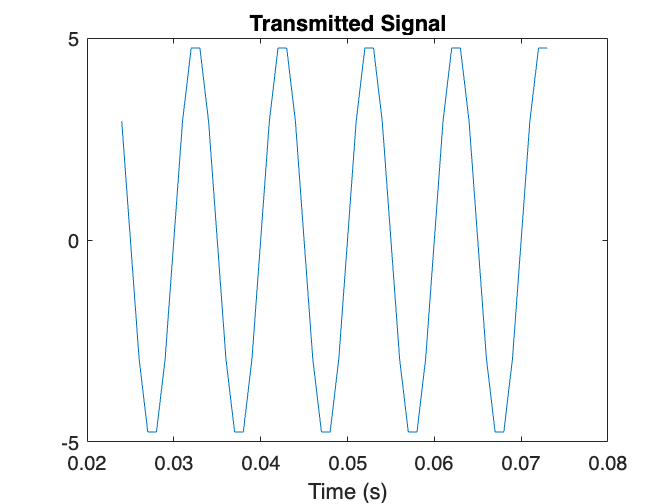

clear;
t = 0:1/1000:1-(1/1000);
s = 5*sin(2*pi*t(25:75-1)*100);
plot(t(25:75-1),s);
xlabel("Time (s)")
title("Transmitted Signal")

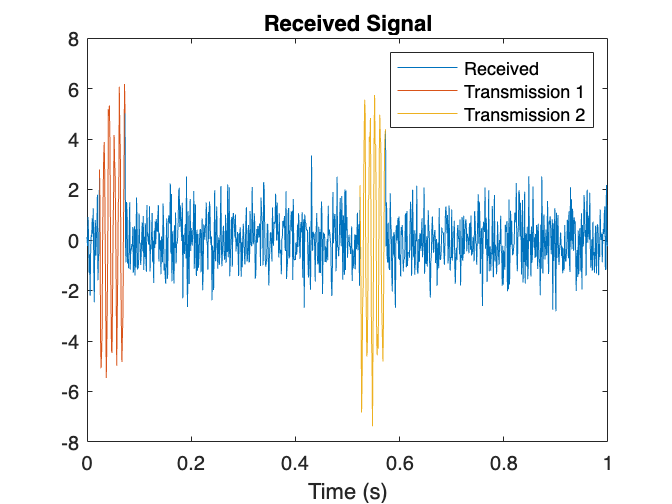

n = randn(size(t));
y = n;
y(25:75-1) = s + n(25:75-1);
y(525:575-1) = s + n(525:575-1);
plot(t,y);
hold on;
plot(t(25:75-1),y(25:75-1));
plot(t(525:575-1),y(525:575-1));
xlabel("Time (s)")
title("Received Signal")
legend({"Received", "Transmission 1", "Transmission 2"});
hold off;

Run classification through clustering:

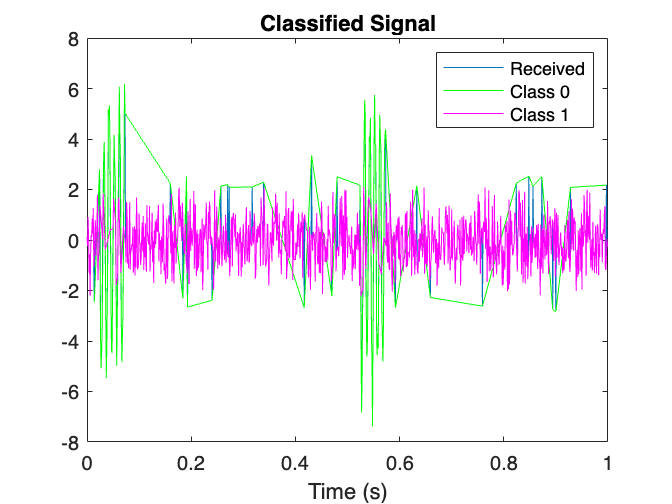

Classify = EstParm(y, 1000, 1);
plot(t,y);
hold on;
plot(t(Classify==0),y(Classify==0),'green');
plot(t(Classify==1),y(Classify==1),'magenta');
xlabel("Time (s)")
title("Classified Signal")
legend({"Received","Class 0", "Class 1"});